load loaddataset.mat

% Configuration:
alg = 'trainlm';% First training algorithm to use
H = 50;% Number of neurons in the hidden layer
delta_epochs = [1,9,90,900];% Number of epochs to train in each step
epochs = cumsum(delta_epochs);


%creation of networks
net=feedforwardnet(H,alg);
% configure the transfer function 
% logsig
% tansig
% pureline
net.layers{1}.transferFcn = 'tansig';
net=configure(net,x_train,t_train);% Set the input and output sizes of the net
net.divideFcn = 'dividetrain';% Use training set only (no validation and test split)
net=init(net);% Initialize the weights (randomly)

%training 
net.trainParam.epochs=delta_epochs(1);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks
t1=sim(net,x_train);
v1=sim(net,x_val);
perf_t1 = perform(net,t_train,t1)

perf_t1 = 0.0488

perf_v1 = perform(net,t_val,v1)

perf_v1 = 0.0500



net.trainParam.epochs=delta_epochs(2);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks
t2=sim(net,x_train);
v2=sim(net,x_val);
perf_t2 = perform(net,t_train,t2)

perf_t2 = 0.0033

perf_v2 = perform(net,t_val,v2)

perf_v2 = 0.0056


net.trainParam.epochs=delta_epochs(3);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks
t3=sim(net,x_train);
v3=sim(net,x_val);
perf_t3 = perform(net,t_train,t3)

perf_t3 = 1.2999e-05

perf_v3 = perform(net,t_val,v3)

perf_v3 = 1.2909e-04


net.trainParam.epochs=delta_epochs(4);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks
t4=sim(net,x_train);
v4=sim(net,x_val);
perf_t4 = perform(net,t_train,t4)

perf_t4 = 1.1518e-07

perf_v4 = perform(net,t_val,v4)

perf_v4 = 1.1545e-05

MSE_Train = [perf_t1 perf_t2 perf_t3 perf_t4] 

MSE_Train =     0.0488    0.0033    0.0000    0.0000


MSE_Val = [perf_v1 perf_v2 perf_v3 perf_v4] 

MSE_Val =     0.0500    0.0056    0.0001    0.0000


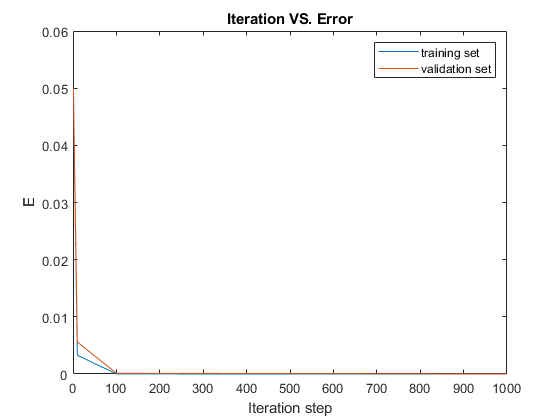

figure('Name','Iteration VS. Error')

plot(epochs, MSE_Train, epochs, MSE_Val)
legend('training set','validation set');
title('Iteration VS. Error');
xlabel('Iteration step');
ylabel('E');